# HW3 Q1a

Consider the non-minimum phase plant G(s) = −s+3/(s+2)(s+1000) and the problem of inverse-based controller design. Assuming that the system has a time delay of 5 ms, and that we desire a 40 dB/dec slope starting a decade above and below the crossover frequency, design an inverse-based controller that maximizes the crossover frequency while achieving a gain margin of 6 dB and a phase margin of 40 degrees. Show the stability margin of the final achieved loop shape along with the sensitivity function.

s = tf('s');
G = (-s+3)/(s+2)/(s+1000);
delay = exp(-0.005 * s);%Build a plant model with a lightly damped mode
G_delay = ((-s+3)/(s+2)/(s+1000)) * delay;
wc = 1.04; %Set the crossover frequency - can get any value we want!
a = 0.1;  %Choose these somewhat arbitrarily to get 40 degree PM
b = 10;    %Choose for 40 degree PM

Control design

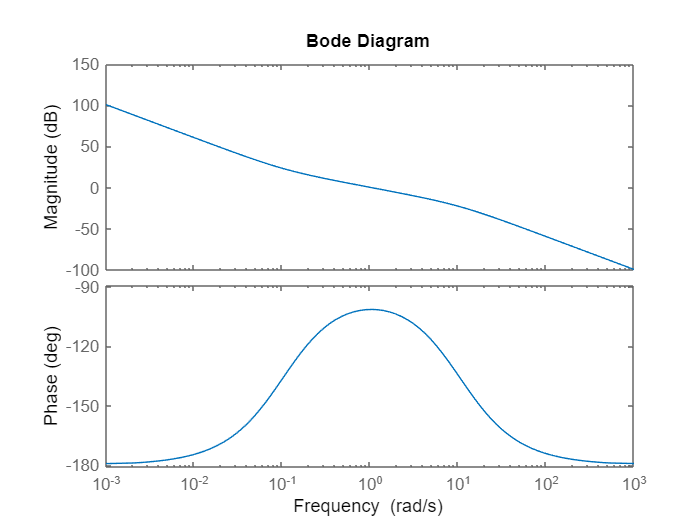

L = (s+a*wc)/s^2/(s+b*wc);  %Build desired loopshape
[mag,~] = bode(L,wc);  %Find gain adjustment
figure
bode(L/mag)  %The desired loopshape

Now design the controller using inversion

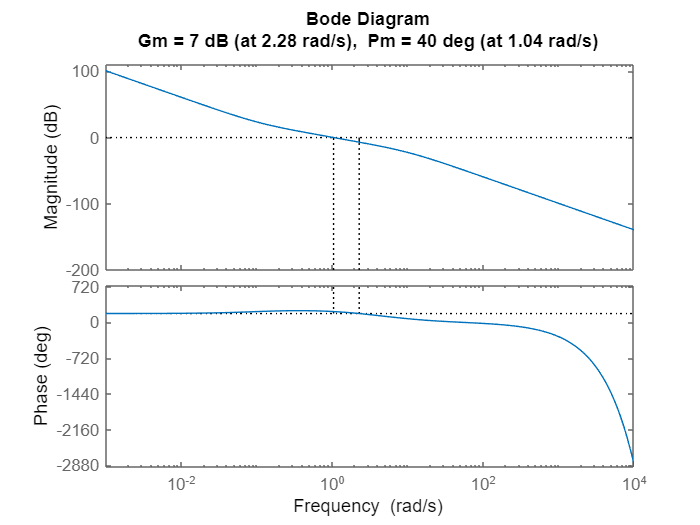

K2 = L * ((s+2)*(s+1000)/(s+3));
[mag2,phase] = bode(K2 * G_delay, wc);  %Find gain adjustment
K2 = K2/mag2;
margin(G_delay * K2)  %We still have a ton of gain margin!

Sensitivity function:

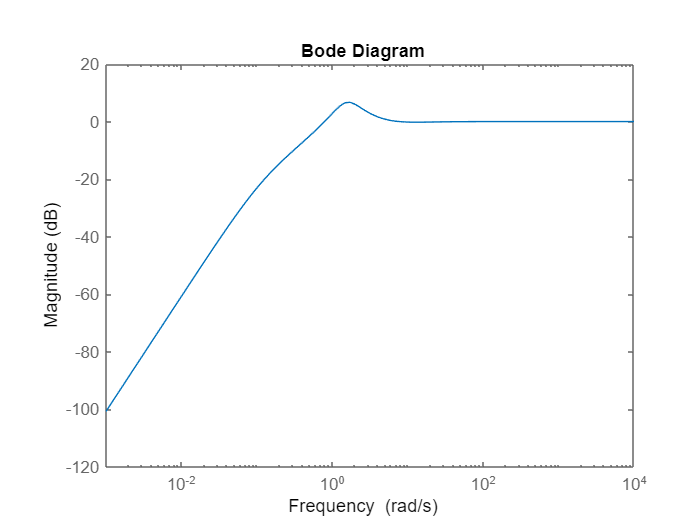

S_I = 1/(1+G_delay*K2);
bodemag(S_I)  %This is the sensitivity function - looks good

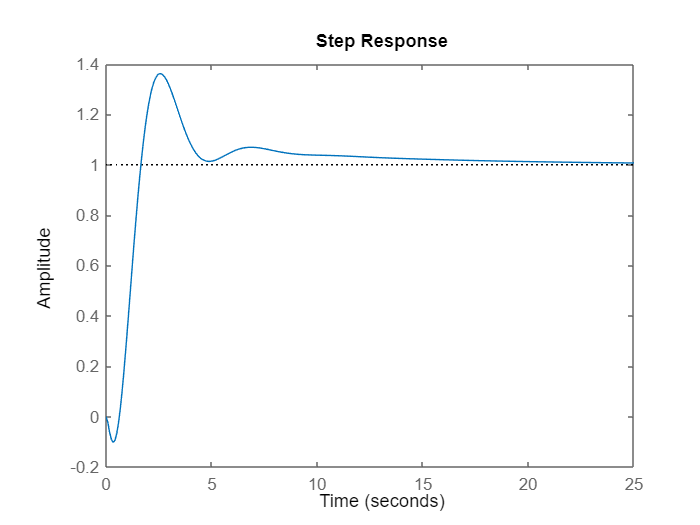

step(feedback(G_delay*K2,1))  %Very fast response

# HW3 Q1b

The inverse-based design breaks down for an unstable plant. Consider the plant G(s) = s+5/(−s+1)(s+1000) without a time delay. Using any method of your choice, design a feedback controller for this system that achieves an open loop crossover of at least 1000 rad/s with a GM ≥ 6dB and a PM ≥ 30 degrees. Use the margin command to demonstrate success and plot the sensitivity function.

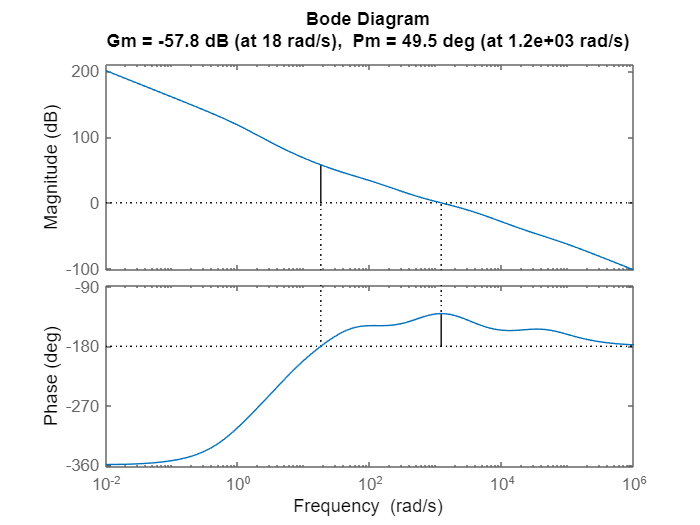

clc;
clear all;
s = tf('s');
G = (s+5)/(-s+1)/(s+1000);
wc = 1200;
[K,CL,GAM] = loopsyn(pade(G,5),wc^2/s^2); %G: plant Gd: target loop shape 5:how much expand
%N = norm(1-CL,'inf');
margin(G * K)  %We still have a ton of gain margin!

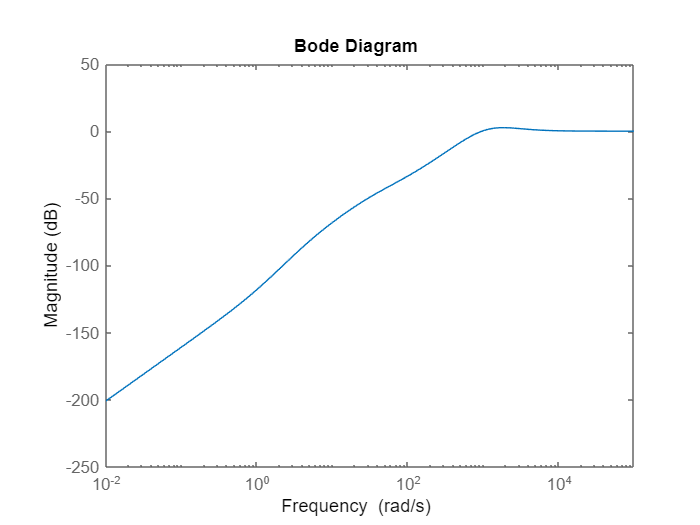

bodemag(1-CL) %sensitivity function

# HW3 Q2a

Using the single stage HDD model in file HDDModel.m, design a controller that achieves 60 dB low frequency attenuation, a 3 kHz sensitivity zero dB crossing, and a sensitivity peak no greater than 6 dB. Do this for both first and 2nd order sensitivity weights. Submit the following plots: 1.) sensitivity functions for both designs along with desired sensitivity functions; 2.) step response of both closed loop systems. Given the same specs, is there is a limit to the sensitivity crossing frequency for the 2nd order sensitivity weight?

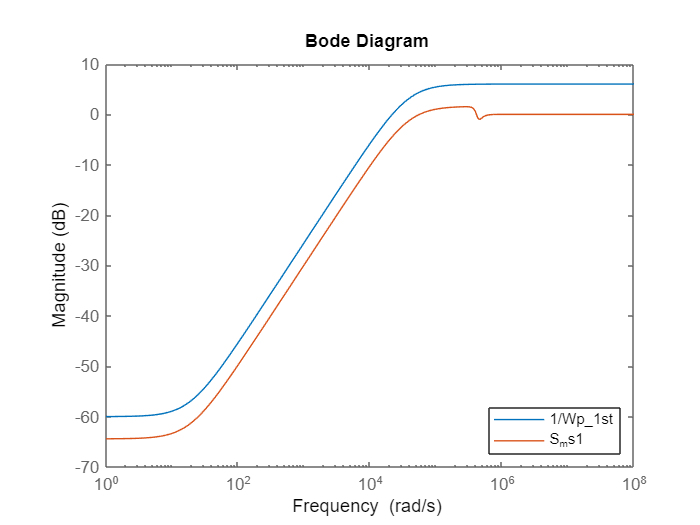

%Mixed sensitivty design for a flexible structure with a RHP zero
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
P = Gv*Gv1*Gv2*Gv3*Gv4;
s = tf('s');  
G = P;
%Design goals
M = 2;  %Maximum sensitivity peak - not a bad general rule of thumb
A = 1000;  %Low frequency attenuation
BW = 18849; %Trivial low value for bandwidth
Wp_1st = ((s/M)+BW)/(s+BW/A);
Wp_2nd = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;
[K1,CL1,GAM1,info1] = mixsyn(G,Wp_1st,[],[]); 
[K2,CL2,GAM2,info2] = mixsyn(G,Wp_2nd,[],[]); 

L_ms1 = G * K1;
S_ms1 = 1/(1+L_ms1); %sensitivity function
T_ms1 = 1-S_ms1; %complementary sensitivity function

L_ms2 = G * K2;
S_ms2 = 1/(1+L_ms2); %sensitivity function
T_ms2 = 1-S_ms2; %complementary sensitivity function

figure
bodemag(1/Wp_1st,S_ms1) %1/Wp_1st desired, S_ms1 designed
legend('1/Wp_1st','S_ms1','location', 'SouthEast')

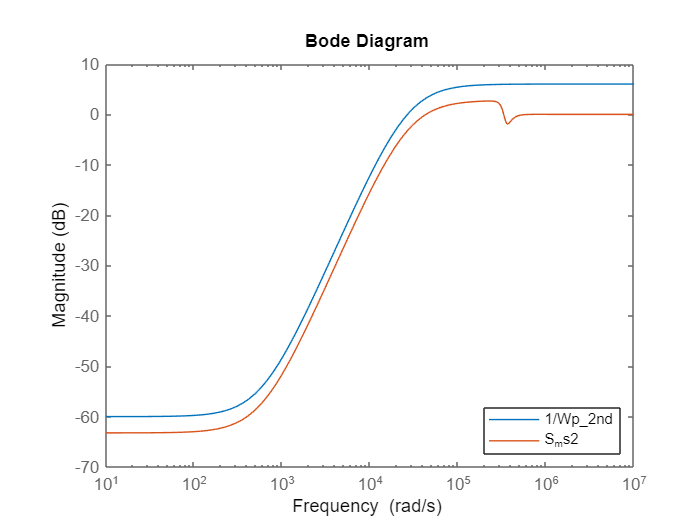

figure
bodemag(1/Wp_2nd,S_ms2) %1/Wp_2nd desired, S_ms2 designed
legend('1/Wp_2nd','S_ms2','location', 'SouthEast')

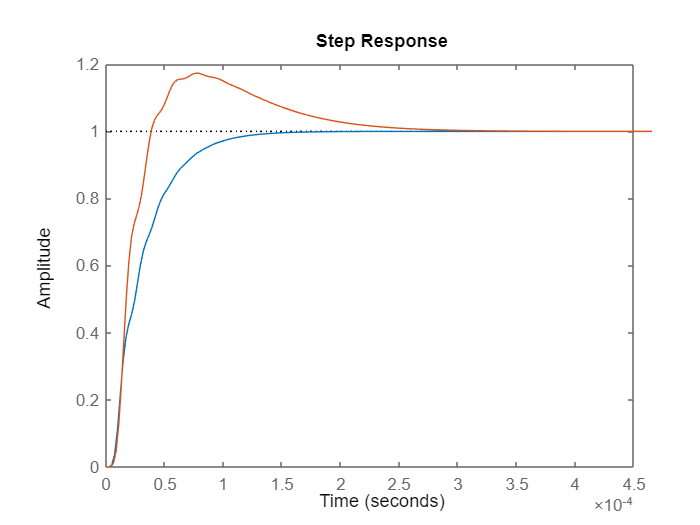

figure
step(feedback(G * K1, 1),feedback(G * K2, 1))

# HW3 Q2b

Now let’s add a complementary sensitivity weight to ensure that the high frequency gain is low. For a successful design (γ < 1), our weights must satisfy 1/Wp + 1/WT ≥1, or else we violate the fundamental constraint S + T = 1. Create a complementary sensitivity weight that ensures a 20 dB/dec rolloff at high frequencies with crossover frequency of 10000 Hz. Using the 2nd order performance weight from Part a, perform the mixed sensitivity design and plot the weights against the sensitivity and complementary sensitivity function.

%Mixed sensitivty design for a flexible structure with a RHP zero
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
P = Gv*Gv1*Gv2*Gv3*Gv4;
s = tf('s');  
G = P;

## Parameters

BW_p = 18849;
BW_t = 62831.853;
M = 2; % sensitivity peak
A = 1000; %Low frequency attenuation
Mt = 3;%Maximum complementary sensitivity peak ?? The question is slope? How to find Mt At?
At = 0.001;  %High frequency noise attenuation ??
Wp_2nd = (s/sqrt(M)+BW_p)^2/(s+BW_p/sqrt(A))^2;
Wt = makeweight(1/Mt,BW_t,1/At);  %The 3x bandwidth is to give some separation between the requirements % 1/Wp + 1/WT ≥1 
[K2,CL2,GAM2,info2] = mixsyn(G,Wp_2nd,[],Wt);
GAM2

GAM2 = 1.1964

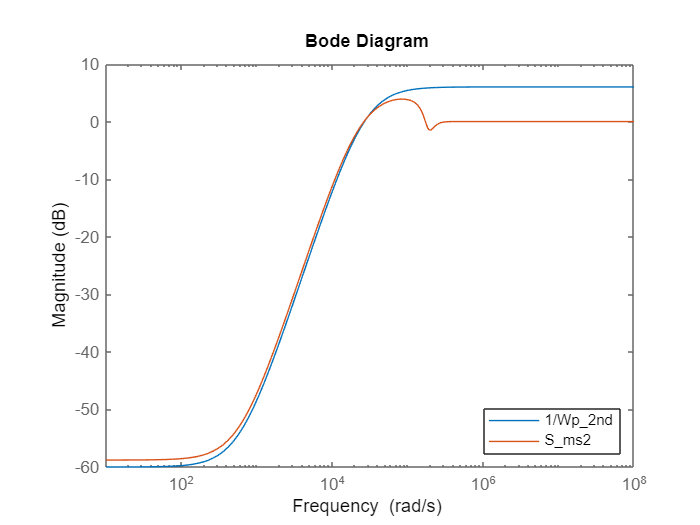

L_ms2 = G * K2;
S_ms2 = 1/(1+L_ms2); %sensitivity function
T_ms2 = 1-S_ms2; %complementary sensitivity function

figure
bodemag(1/Wp_2nd,S_ms2) %Compare with performance
legend('1/Wp_2nd','S_{ms2}','location', 'SouthEast')

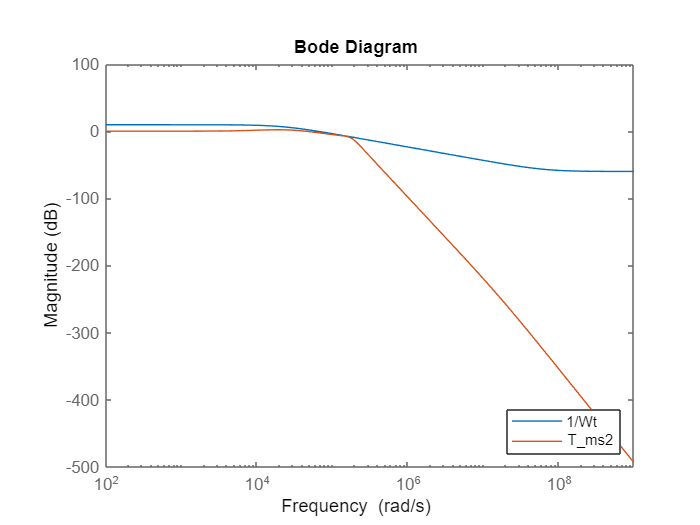

figure
bodemag(1/Wt,T_ms2); %Compare with control robustness
legend('1/Wt','T_{ms2}','location', 'SouthEast')

# HW3 Q2c

Now let’s add a control weight in its simplest form. Assume that the actuator’s saturation limit is 100, and design constant weight Wu = 1/100. You will NOT achieve a value of γ < 1 for this design using the bandwidths from above. Write a script to maximize the bandwidth such that γ < 1 using the controller weight, a 2nd order performance weight as in Part a, and a 1st order complementary sensitivity weight with crossover 5x higher than the performance weight crossover. Plot the weights vs. their respective sensitivity functions, and compute the final H∞ norm using the norm command in Matlab. 

clc;
clear all;
%Mixed sensitivty design for a flexible structure with a RHP zero
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
P = Gv*Gv1*Gv2*Gv3*Gv4;
s = tf('s');  
G = P;

## **Parameters**

M = 2;  %Maximum sensitivity peak from part a
A = 1000;  %Low frequency attenuation from part a
Mt = 2;  %Maximum complementary sensitivity peak: actuator's saturation limit?
At = 0.001;  %High frequency noise attenuation from part b
GAM = 0;  %Dummy value to start
BW = 0.5; %Trivial low value for bandwidth
BW_step = 1;
Wp = 0; %Performance weight
Wu = 1/100;  %Control weight
K = 0;

## Maximize crossover

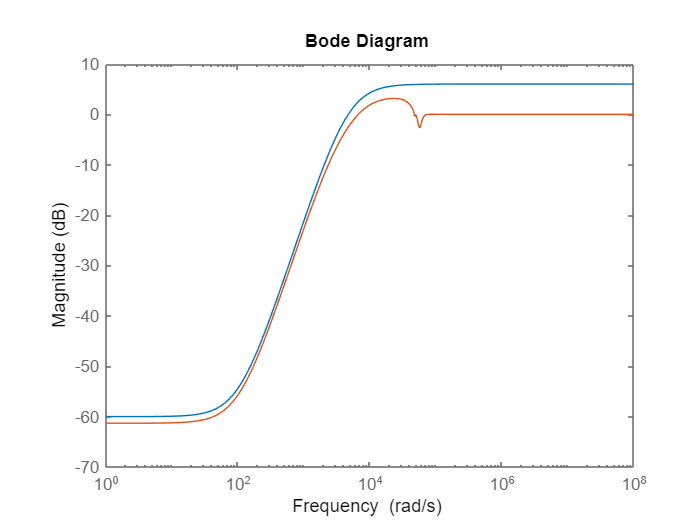

while GAM<1
    Wp_old = Wp;
    Wp = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;
    Wt = makeweight(1/Mt,5*BW,1/At);  %The 5x bandwidth is to give some separation between the requirements
    K_old = K;
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,Wt);  %This is the magic synthesis command.  Much of this class is about how and why this works.  NOTE:  For comparison to loopsyn below, be sure to use [],[] for 2nd two arguments.
    BW = BW+BW_step;  %Bisection would be cleaner, but this works!
end

L_ms = G * K_old;
S_ms = 1/(1+L_ms);
T_ms = 1-S_ms;

figure
bodemag(1/Wp_old,S_ms) %Compare with performance

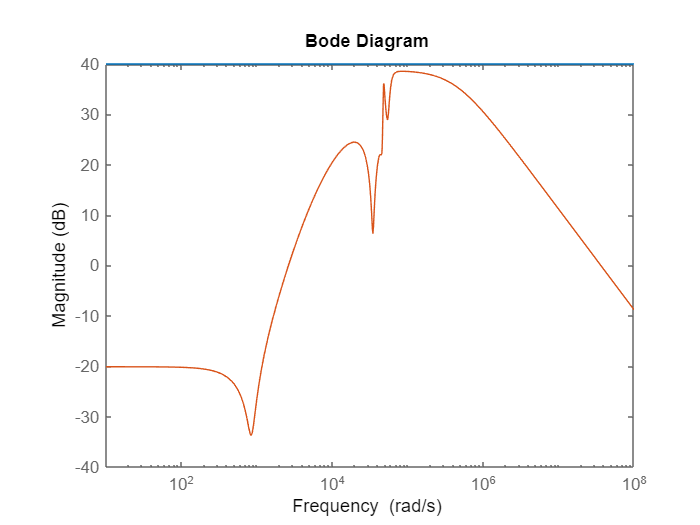

figure
bodemag(tf(1/Wu,1),K*S_ms); %Compare with control effort

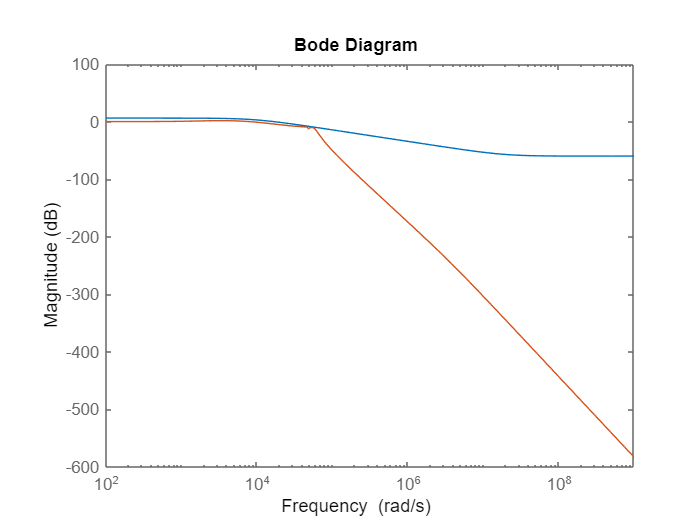

figure
bodemag(1/Wt,T_ms); %Compare with control robustness

N = [norm(Wp_old * S_ms,"inf");norm(Wu * K_old * S_ms,"inf");norm(Wt * T_ms,"inf")]

N =        Inf
    0.8523
    0.8719


# HW3 Q3a MIMO

The file HDDModel DS.m includes the plant model for a dual-stage hard disk drive. This includes the single stage model from Problem 2 along with a model of a secondary stage actuator, with the total system output given by 

y=VCM·uVCM +PZT·uPZT. 

Our goal is to **increase system bandwidth** using the secondary actuation stage, while respecting the limits of actuator saturation. When loading the file, the two relevant models are VCM and PZT. Create a DISO model in Matlab (think about the dimensions of a 2 input, 1 output system and create a transfer function matrix) and plot the Bode plot. 

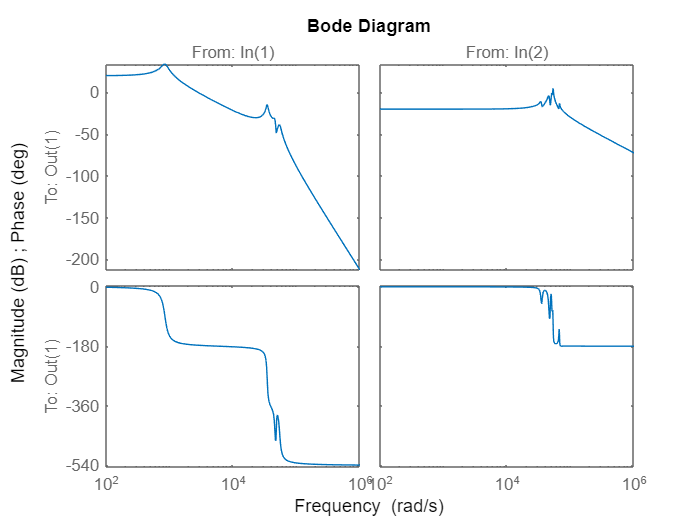

s = tf('s');
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4;
Gp = 0.1;  %DC gain
Gp1 = tf((2*pi*8460)^2,[1 2*0.01*2*pi*8460 (2*pi*8460)^2]);
Gp2 = 5500^2/5650^2*tf([1 2*.03*2*pi*5650 (2*pi*5650)^2],[1 2*.03*2*pi*5500 (2*pi*5500)^2]);
Gp3 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
Gp4 = 8070^2/8250^2*tf([1 2*.02*2*pi*8250 (2*pi*8250)^2],[1 2*.015*2*pi*8070 (2*pi*8070)^2]);
Gp5 = 10650^2/10530^2*tf([1 2*.015*2*pi*10530 (2*pi*10530)^2],[1 2*.01*2*pi*10650 (2*pi*10650)^2]);
PZT = Gp*Gp1*Gp2*Gp3*Gp4*Gp5;
G = [VCM PZT];
bode(G)

# HW3 Q3b 

The dual-stage design problem requires us to use a performance weight as in Problem 2a while designing appropriate control weights for the two actuation stages. Assign the VCM an actuation penalty assuming its maximum output is 100, and give the PZT a constant actuator penalty given that its maximum output is 10 (you will need to think about the dimensions when you put this into mixsyn). Perform a mixed sensitivity design using a 2nd order performance weight with the same specs as Problem 2(c) in terms of complementary sensitivity weight. As in Problem 2(c), maximize the bandwidth such that γ < 1. Plot the achieved sensitivity function along with its performance weight and plot the Bode magnitude plot of WUKS to show that the actuation limits hold. 

clc;
clear all;
s = tf("s");
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4;
Gp = 0.1;  %DC gain
Gp1 = tf((2*pi*8460)^2,[1 2*0.01*2*pi*8460 (2*pi*8460)^2]);
Gp2 = 5500^2/5650^2*tf([1 2*.03*2*pi*5650 (2*pi*5650)^2],[1 2*.03*2*pi*5500 (2*pi*5500)^2]);
Gp3 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
Gp4 = 8070^2/8250^2*tf([1 2*.02*2*pi*8250 (2*pi*8250)^2],[1 2*.015*2*pi*8070 (2*pi*8070)^2]);
Gp5 = 10650^2/10530^2*tf([1 2*.015*2*pi*10530 (2*pi*10530)^2],[1 2*.01*2*pi*10650 (2*pi*10650)^2]);
PZT = Gp*Gp1*Gp2*Gp3*Gp4*Gp5;
G = [VCM PZT];

M = 2;  %Maximum sensitivity peak from part a
A = 1000;  %Low frequency attenuation from part a
Mt = 2;  %Maximum complementary sensitivity peak: actuator's saturation limit?
At = 0.001;  %High frequency noise attenuation from part b
GAM = 0;  %Dummy value to start
BW = 1000; %Trivial low value for bandwidth
BW_step = 5;
Wp = 0; %Performance weight
Wu_VCM = 1/100;  %Control weight
Wu_PZT = 1/10;
Wu = [Wu_VCM 0; 0 Wu_PZT];
K = 0;

## Maximize crossover bandwidth

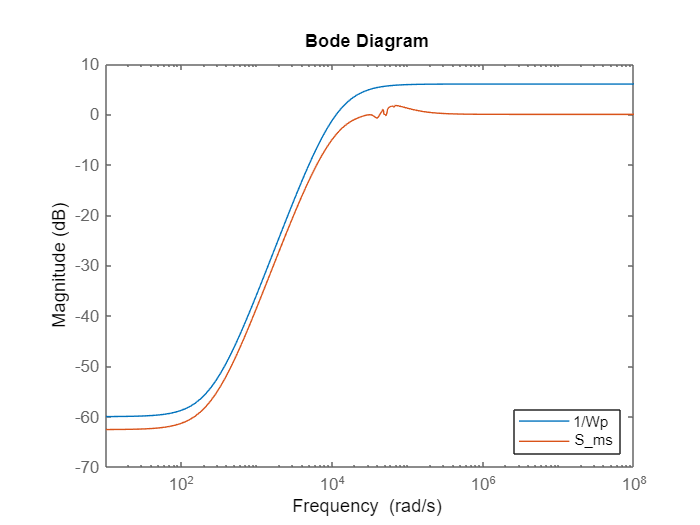

while GAM<1
    Wp_old = Wp;
    Wp = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;
    Wt = makeweight(1/Mt,5*BW,1/At);  %The 5x bandwidth is to give some separation between the requirements
    K_old = K;
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,Wt);  %This is the magic synthesis command.  Much of this class is about how and why this works.  NOTE:  For comparison to loopsyn below, be sure to use [],[] for 2nd two arguments.
    BW = BW+BW_step;  %Bisection would be cleaner, but this works!
end
L_ms = G * K_old;
S_ms = 1/(1+L_ms);
T_ms = 1-S_ms;
figure
bodemag(1/Wp_old,S_ms) %Compare with performance
legend('1/Wp','S_{ms}','location', 'SouthEast')

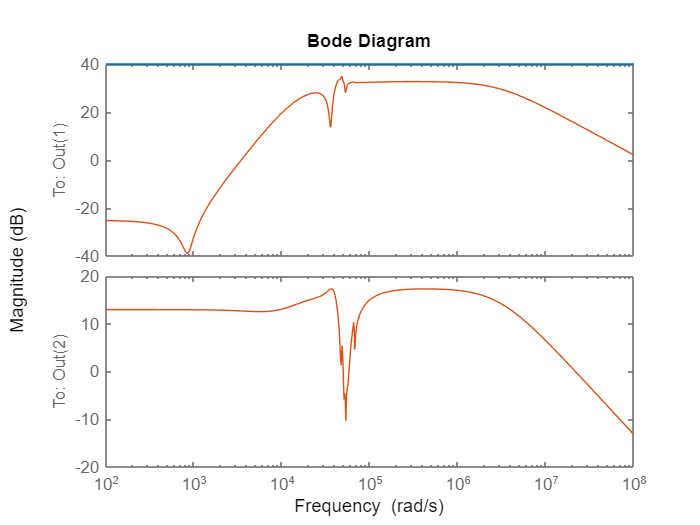

figure
bodemag(tf(1/Wu(1,1),1),K_old*S_ms);

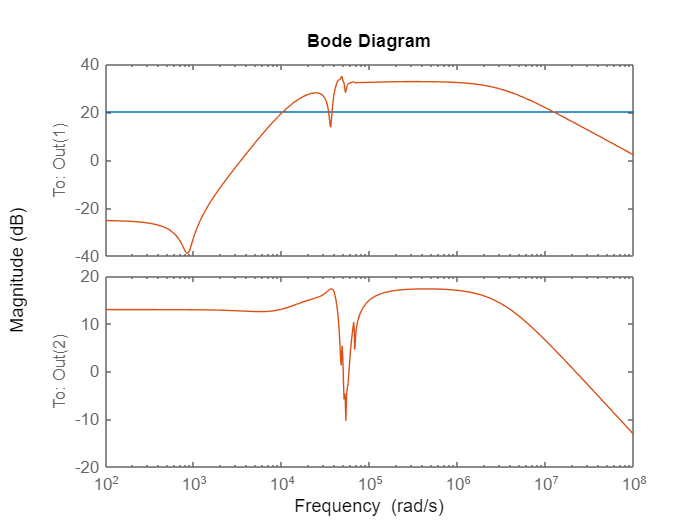

figure
bodemag(tf(1/Wu(2,2),1),K_old*S_ms);